# Lesson 3

Written by Brenda So and Cory Nezin

# Objective

After this class, you should be able to:

- Perform logical and relational indexing

- Know how to write anonymous and normal functions

# Review on Basic Indexing

Let's start off with some basic indexing we've seen earlier. This is from the previous lesson script:

x = [16 5 9 4 2 11 7 14];
x(:);    % Index the whole x vector
x(1);    % Index the first element in x
x(2:5);  % Index the second to fifth element in x (inclusively)
x(end);  % Index the last element in x

# Indexing Vectors

The review already showed you some examples of vector indexing. Another thing to note is that you can use a vector to index a vector. This could be particularly useful if you want to obtain a range of values in a single vector. 

x([1 3 5 7])    % Indexing the 1,3,5,7th element in x

ans =     16     9     2     7


x(1:2:7)        % You're basically doing the same thing as above

ans =     16     9     2     7


x([5:8 1:4])    % WRITEME IN COMMENTS! : What does this line do?

ans =      2    11     7    14    16     5     9     4


x([1:4]) = 40   % WRITEME IN COMMENTS! : What does this line do?

x =     40    40    40    40     2    11     7    14


# Indexing Matrices with Two subscripts

Indexing with 2 subscripts is very intuitive: you would specify the row first, and then the column. 

A = [16 2 3 13; 5 11 10 8; 9 7 6 12; 4 14 15 1];
A(1,4)    % Extract the element in row 1, column 4

ans = 13

You can also extent it into the more general case, where one or both of the row and column can be vectors

A(1:3, 1:2)    % WRITEME IN COMMENTS!: What do I do?

ans =     16     2
     5    11
     9     7


A(end,:)       % WRITEME IN COMMENTS!: What do I do?

ans =      4    14    15     1


A(:,3)         % WRITEME IN COMMENTS!: What do I do? 

ans =      3
    10
     6
    15


However, indexing with 2 subscripts has its limitations. For example, suppose you want to extract (2,1), (3,2), (4,4) elements from A. One might intuitively think to do the following, but it wouldn't work! The picture illustrates what is actually happening!

A([2 3 4],[1 2 4])    % It doesn't work! WHY?

ans =      5    11     8
     9     7    12
     4    14     1


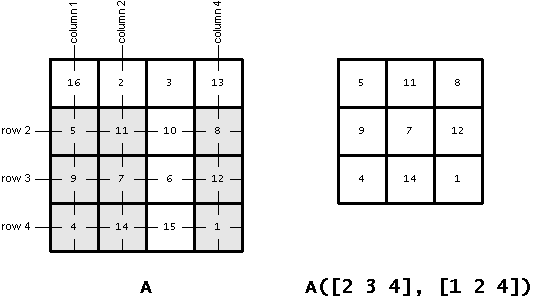

# Linear indexing

When you index into A with only 1 subscript, MATLAB flattens the matrix into one long column

A(:)

ans =     16
     5
     9
     4
     2
    11
     7
    14
     3
    10


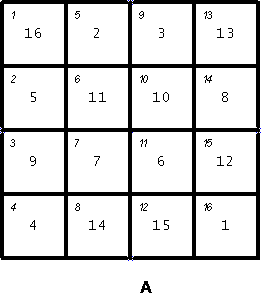

A(14)    % WRITEME INCOMMENTS: What does this give you?

ans = 8

Consider the aforementioned problem again: To index (2,1), (3,2), (4,4), you'll need to do 

A([2 7 16])

ans =      5     7     1


But lucky enough, MATLAB has a function that would calculate the linear index for you!

ind = sub2ind(size(A),[2 3 4],[1 2 4])

ind =      2     7    16


# Logical Operators

Before we discuss logical indexing,we need to address the idea of logic in MATLAB. You should all know what and, or, and not is from DLD. In MATLAB, you can apply such concepts for logical arrays. Logical arrays are arrays of 0(false) and 1(true). Note that an array of 0 and 1 might not necessary be a logical array, but you can convert a normal array to a logical array.

B = eye(4);
C = logical([1 1 1 1; 1 0 0 0; 1 0 0 0; 1 0 0 0]);
islogical(B)

ans = logical
   0


islogical(C)

ans = logical
   1


logical(B);

B & C;      % and(B,C) is equivalent to B&C
B | C;      % or(B,C) is equivalent to B|C
~(B & C);   % not(and(B,C)) is equivalent to ~(B&C)
not(B & C); % you can use both representations intermittenly 

true(2,5)   % creates a 2-by-5 matrix with all elements = 1

ans = 2×5 logical array
   1   1   1   1   1
   1   1   1   1   1


Note: not(2) and not(-2) both give you one, only not(0) gives you zero. 

# Logical Indexing *** VERY IMPORTANT ***

Another indexing variation, *logical indexing*, has proven to be both useful and expressive. In logical indexing, you use a single, logical array for the matrix subscript. MATLAB extracts the matrix elements corresponding to the nonzero values of the logical array. The output is always in the form of a column vector. For example, `A(A > 12)` extracts all the elements of `A` that are greater than 12. 

A(A > 12)

ans =     16
    14
    15
    13


The expression A > 12 creates a logical array, where each element would show 1 if the expression evaluates to true, and false vice versa

A > 12

ans = 4×4 logical array
   1   0   0   1
   0   0   0   0
   0   0   0   0
   0   1   1   0


And if you want to find the index where A > 12, you can write

find(A > 12)

ans =      1
     8
    12
    13


# Functions

In MATLAB, there are 2 types of functions -- anonymous functions and inline function. Writing functions is very important in MATLAB. Namely, if you have 10 lines of code that is going to be applied 1000 times with different variables names, you shouldn't have to write 10,000 lines of code! There are 2 types of functions in MATLAB, namely anonymous and normal functions. 

# Anonymous Function

Anonymous functions do not need a separate file, provided that the function itself is a one-liner. 

s = @(x) sin(1./x);
y = s(pi);
y_range = s(0:0.01:2*pi);

# Normal functions

Normally, functions are declared in another file, and we can only use the function that is the NAME of the file. Note that the local functions declared in myFunction.m cannot be used. (Go to lesson3_fn_demo.m to try it out!)

# Lab : Matrix Wrap Around

1. **Find the Peak:** Create a matrix with magic(5) and find the maximum of each row. Afterwards, set all numbers, except for the peak, to be zero. A hint would be to use *help max* to find out how to take the maximum of each row.

% WRITEME: Find the Peak
% STEP 1 : Create a magic matrix of size 5 x 5, store it in A
% STEP 2 : Create a column vector b, which stores the max of each row in A
% STEP 3 : Use the built-in find function, find the index at which A is equal to b, and store it as c
% STEP 4 : Create another matrix of size 5 x 5, initialize all elements to 0 with built-in zeros function, store it in C
% STEP 5 : Set the elements in C where its index in A gives you the max to be b

2. **Matrix Wrap Around:** Write a function which given a vector of distinct points $xVec=\text{ }\left\lbrack x_1 ,x_{2\text{ }} ,\ldotp \ldotp \ldotp ,x_N \right\rbrack$and a point $x$, finds the index $i^\ast $ such that $x_{i^\ast  } \le x$ and$x_{\left(i^\ast  +1\right)} >x$. You may assumed that the points are ordered and distinct, $x_i <x_{i+1} ,1\le i\le N-1$, but you should not assume that the points are equidistantly spaced. You may also assume that $x_1 \le x\le x_n$. You can do either anonymous or general function. Hint: Use the built-in function* find *and *max*.

Save the function in the file *findPivot.m*, and run your function for two cases: $x=\frac{1}{\sqrt{2}}$ and $xVec=0\ldotp 01\ast \left\lbrack 0:100\right\rbrack$; $x=0\ldotp 5$ and $xVec=sort\left(rand\left(1,100\right)\right)$

% WRITEME: Matrix Wrap Around : For anonymous functions